# Chapter 3, Section 4 (Part 1)

The goal of this activity is to introduce what are known as the coordinates of a vector $\vec v$ in a vector space $V$ relative to a basis $B$ for the vector space $V$.

**Definition:** An **ordered basis **of a vector space $V$ is a fixed sequence of linear independent vectors that span $V$.

**Coordinates:** Let $B=\left\{\vec v_1,\ \vec v_2,\ \ldots,\ \vec v_n\right\}$ be an ordered basis for the vector space $V$ and let $c_1$, $c_2$, ... , $c_n$ be the unique scalars such that


$$\vec v=c_1\vec v_1+c_2\vec v_2+\cdots+c_n\vec v_n$$


Then, $c_1$, $c_2$, ... , $c_n$ are called the **coordinates** of $\vec v$ relative to $B$. In this case we write


$$\left[\vec v\right]_B=\pmatrix{c_1\cr c_2\cr\vdots\cr c_n}$$


and refer to the vector $\left[\vec v\right]_B$ as the **coordinate vector** relative to $B$.

# Example #1

Find the vector $\vec v$ determined by the coordinate vector $\left[\vec v\right]_B$ and the given basis $B=\left\{\vec b_1,\ \vec b_2\right\}$, where


$$\vec b_1={\pmatrix{1\cr 1},\qquad\vec b_2= \pmatrix{-2\cr 1}\qquad\text{and}\qquad\left[\vec v\right]_B=\pmatrix{3\cr 2}$$


**Solution:** Using our definition above, we can write:


$$\begin{array}{rcl}
\vec v&=&3\vec b_1+2\vec b_2\\
\vec v&=&3\pmatrix{1\cr 1}+2\pmatrix{-2\cr 1}\\
\vec v&=&\pmatrix{3\cr 3}+\pmatrix{-4\cr 2}\\
\vec v&=&\pmatrix{-1\cr 5}
\end{array}$$


Now, let's visualize our answer so that we can better understand what is going on.

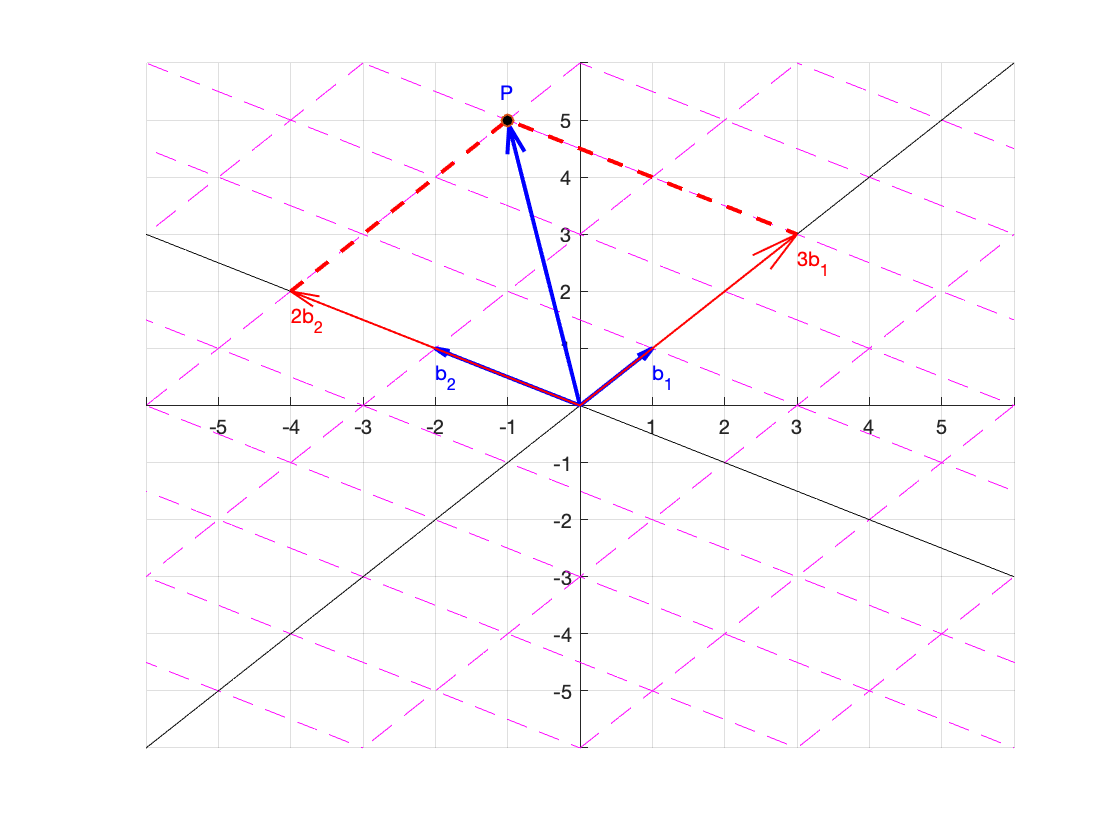

figure, hold on
t=linspace(-6,6);
for k=-5:5
    plot(-2*k+t,k+t,'LineStyle','--','Color','m')
    plot(k-2*t,k+t,'LineStyle','--','Color','m')
end
plot(t,t,'k-')
plot(-2*t,t,'k-')
quiver(0,0,1,1,0,'LineWidth',2,'Color','b','MaxHeadSize',0.7)
quiver(0,0,-2,1,0,'LineWidth',2,'Color','b','MaxHeadSize',0.3)
quiver(0,0,-1,5,0.98,'LineWidth',2,'Color','b','MaxHeadSize',0.3)
quiver(0,0,3,3,0,'LineWidth',1,'Color','r','MaxHeadSize',0.7)
quiver(0,0,-4,2,0,'LineWidth',1,'Color','r','MaxHeadSize',0.3)
line([-4,-1,3],[2 5 3],'LineStyle','--','LineWidth',2,'Color','r')
plot(-1,5,'o','MarkerFaceColor','k')
grid on
xticks(-6:6)
yticks(-6:6)
axis([-6,6,-6,6])
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
text(1,0.5,'b_1','Color','b')
text(-2,0.5,'b_2','Color','b')
text(-1.1,5.5,'P','Color','b')
text(3,2.5,'3b_1','Color','r')
text(-4,1.5,'2b_2','Color','r')
hold off

There are several things to note in this image.

- There are two coordinate systems displayed by two sets of gridlines, one (in red) based on the vectors $\vec b_1=(1,1)^T$ and $\vec b_2=(-2,1)^T$, and the other (in black) on the standard basis $\vec e_1=(1,0)^T$ and $\vec e_2=(0,1)^T$.

- In the standard basis coordinate system, the coordinates of the point $P$ are $\vec v=\pmatrix{-1\cr 5}$.

- In the coordinate system based on $B=\left\{\pmatrix{1\cr 1},\ \pmatrix{-2\cr 1}\right\}$, the coordinates of the point $P$ are $\left[\vec v\right]_B=\pmatrix{3\cr 2}$.

# Example #2

Find the coordinate vector $\left[\vec v\right]_B$ of $\vec v$ relative to the given basis $B=\left\{\vec b_1,\  \vec b_2\right\}$, where


$$\vec b_1=\pmatrix{1\cr 1},\qquad \vec b_2=\pmatrix{-2\cr 1},\qquad\text{and}\qquad \vec v=\pmatrix{{-1\cr -4}$$


**Solution:** Note that this will be the reverse of the process we did in Example #1, where we were given $\left[\vec v\right]_B$ and asked to find $\vec v$. This time we are given $\vec v$ and asked to find $\left[\vec v\right]_B$.  So, we want to write $\vec v$ as a linear combination of $\vec b_1$ and $\vec b_2$.


$$\begin{array}{rcl}
c_1\vec b_1+c_2\vec b_2&=&\vec v\\
c_1\pmatrix{1\cr 1}+c_2\pmatrix{-2\cr 1}&=&\pmatrix{-1\cr -4}\\
\pmatrix{1 & -2\cr 1 & 1}\pmatrix{c_1\cr c_2}&=&\pmatrix{-1\cr -4}
\end{array}$$


Set up the augmented matrix and row reduce.


$$\pmatrix{1 & -2 & -1\cr 1 & 1 & -4}\ \matrix{~\cr R_2-R_1}\qquad\longrightarrow\qquad\pmatrix{1 & -2 & -1\cr 0 & 3 & -3}$$


Therefore, we have a system of two linear equations.


$$\begin{array}{rcl}
c_1-2c_2&=&-1\\
3c_2&=&-3
\end{array}$$


The last equation gives us $c_2=-1$. Substituting $c_2=-1$ in the first equation gives us:


$$\begin{array}{rcl}
c_1-2(-1)&=&-1\\
c_1+2&=&-1\\
c_2&=&-3
\end{array}$$


With these answers,  $c_1\vec b_1+c_2\vec b_2=\vec v$ becomes


$$-1\pmatrix{1\cr 1}+(-3)\pmatrix{-2\cr 1}=\pmatrix{-1\cr -4}$$


so the coordinates of $\vec v$ relative to our basis $B$ are:


$$\begin{array}{rcl}
\left[\vec v\right]_B=\pmatrix{c_1\cr c_2}\\
\left[\vec v\right]_B=\pmatrix{-1\cr -3}
\end{array}$$


Again, to better understand what we are doing in this process, we'll visualize our answer.

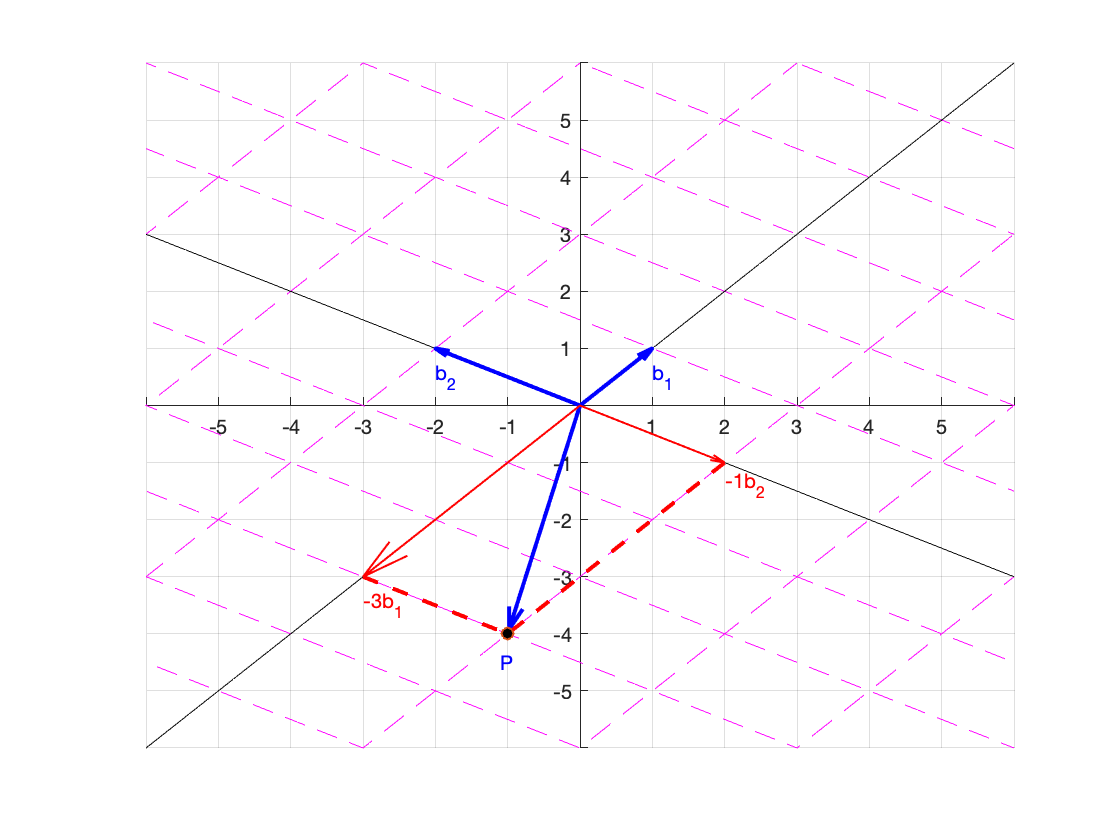

figure, hold on
t=linspace(-6,6);
for k=-5:5
    plot(-2*k+t,k+t,'LineStyle','--','Color','m')
    plot(k-2*t,k+t,'LineStyle','--','Color','m')
end
plot(t,t,'k-')
plot(-2*t,t,'k-')
quiver(0,0,1,1,0,'LineWidth',2,'Color','b','MaxHeadSize',0.7)
quiver(0,0,-2,1,0,'LineWidth',2,'Color','b','MaxHeadSize',0.3)
quiver(0,0,-1,-4,0.98,'LineWidth',2,'Color','b','MaxHeadSize',0.3)
quiver(0,0,-3,-3,0,'LineWidth',1,'Color','r','MaxHeadSize',0.7)
quiver(0,0,2,-1,0,'LineWidth',1,'Color','r','MaxHeadSize',0.3)
line([-3,-1,2],[-3,-4,-1],'LineStyle','--','LineWidth',2,'Color','r')
plot(-1,-4,'o','MarkerFaceColor','k')
grid on
xticks(-6:6)
yticks(-6:6)
axis([-6,6,-6,6])
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
text(1,0.5,'b_1','Color','b')
text(-2,0.5,'b_2','Color','b')
text(-1.1,-4.5,'P','Color','b')
text(-3,-3.5,'-3b_1','Color','r')
text(2,-1.4,'-1b_2','Color','r')
hold off

There are several things to note in this image.

- There are two coordinate systems displayed by two sets of gridlines, one (in red) based on the vectors    $\vec b_1=(1,1)^T$ and $\vec b_2=(-2,1)^T$, and the other (in black) on the standard basis $\vec e_1=(1,0)^T$ and $\vec e_2=(0,1)^T$.

- In the standard basis coordinate system, the coordinates of the point $P$ are $\vec v=\pmatrix{-1\cr -4}$.

- In the coordinate system based on $B=\left\{\pmatrix{1\cr 1},\ \pmatrix{-2\cr 1}\right\}$, the coordinates of the point $P$ are $\left[\vec v\right]_B=\pmatrix{-3\cr -1}$.

# Change of Basis Matrix

Suppose that we have two bases for a vector space $V$ of dimension 2.


$$B=\left\{\vec b_1,\ \vec b_2\right\}\qquad\text{and}\qquad C=\left\{\vec c_1,\ \vec c_2\right\}$$


Now, suppose we are given a vector $\vec v\in V$ and its coordinate vector relative to $B$,


$$\left[\vec v\right]_B=\pmatrix{x_1\cr x_2}$$


or equivalently,


$$\vec v=x_1\vec b_1+x_2\vec b_2$$


How do we find the coordinate vector relative to $C$? The first step is to express $\vec b_1$ and $\vec b_2$ as linear combinations of the vectors in $C$.


$$\begin{array}{rcl}
\vec b_1&=&a_1\vec c_1+a_2\vec c_2\\
\vec b_2&=&d_1\vec c_1+d_2\vec c_2
\end{array}$$


Now we can substitute both these expressions into our linear combination for $\vec v$.


$$\begin{array}{rcl}
\vec v&=&x_1\vec b_1+x_2\vec b_2\\
\vec v&=&x_1(a_1\vec c_1+a_2\vec c_2)+x_2(d_1\vec c_1+d_2\vec c_2)
\end{array}$$


Now we can do a little manipulation.


$$\begin{array}{rcl}
\vec v&=&x_1a_1\vec c_1+x_1a_2\vec c_2+x_2d_1\vec c_1+x_2d_2\vec c_2\\
\vec v&=&(x_1a_1+x_2d_1)\vec c_1+(x_1a_2+x_2d_2)\vec c_2
\end{array}$$


Therefore, we have shown that


$$\left[\vec v\right]_C=\pmatrix{x_1a_1+x_2d_1\cr x_1a_2+x_2d_2}$$


Now, this can be written in matrix form as follows:


$$\left[\vec v\right]_C=\pmatrix{a_1 & d_1\cr a_2 & d_2}\pmatrix{x_1\cr x_2}$$


Recall that  we started above with $\left[\vec v\right]_B=\pmatrix{x_1\cr x_2}$, so when we substitute this into our last line, we get:


$$\left[\vec v\right]_C=\pmatrix{a_1 & d_1\cr a_2 & d_2}\left[\vec v\right]_B$$


The matrix $\pmatrix{a_1 & d_1\cr a_2 & d_2}$ is called the **transition matrix** from $B$ to $C$. 

**Really Important Observation: **At the start, we wrote:


$$\begin{array}{rcl}
\vec b_1&=&a_1\vec c_1+a_2\vec c_2\\
\vec b_2&=&d_1\vec c_1+d_2\vec c_2
\end{array}$$


Note that each of these can be written as follows:


$$\begin{array}{rcl}
\left[\vec b_1\right]_C=\pmatrix{a_1\cr a_2}\\
\left[\vec b_2\right]_C=\pmatrix{d_1\cr d_2}
\end{array}$$


Notice that these are the columns of our transition matrix, so we can also write our final result as follows:


$$\left[\vec v\right]_C=\pmatrix{[\vec b_1]_C & [\vec b_2]_C}\left[\vec v\right]_B$$


Our author uses the following notation for this transition matrix,


$$\left[\vec v\right]_C=[I]_B^C\left[\vec v\right]_B$$


but your instructor will use the following notation for the transition matrix during class and office hours.


$$\left[\vec v\right]_C=P_{C\leftarrow B}\left[\vec v\right]_B$$


After we try an example, we will show you why this notation is extremely helpful.

# Example #3

Given the bases $B=\left\{\vec b_1,\ \vec b_2\right\}$ and $C=\left\{\vec c_1,\ \vec c_2\right\}$ for $R^2$, where


$$\vec b_1=\pmatrix{2\cr 1},\quad \vec b_2=\pmatrix{-1\cr 1}\qquad\text{and}\qquad \vec c_1=\pmatrix{1\cr 1},\quad \vec c_2=\pmatrix{-3\cr 1}$$


find the transition matrix from $B$ to $C$. 

**Solution:** We saw above that the first step is to find the coordinate vectors for $\vec b_1$ and $\vec b_2$ relative to $C$. We'll do $\vec b_1$ first.


$$\begin{array}{rcl}
\vec b_1&=&x_1\vec c_1+x_2\vec c_2\\
\pmatrix{2\cr 1}&=&x_1\pmatrix{1\cr 1}+x_2\pmatrix{-3\cr 1}
\end{array}$$


Set up the augmented matrix and row reduce.


$$\pmatrix{1 & -3 & 2\cr 1 & 1 & 1}\ \matrix{~\cr R_2-R_1}\qquad\longrightarrow\qquad\pmatrix{1 & -3 & 2\cr 0 & 4 & -1}$$


Therefore,


$$\begin{array}{rcl}
x_1-3x_2&=&2\\
4x_2&=&-1
\end{array}$$


Thus, $x_2=-1/4$, and if we substitute this into the first equation, we get:


$$\begin{array}{rcl}
x_1-3\left(-\frac14\right)&=&2\\
x_1+\frac34&=&\frac84\\
x_1&=&\frac54
\end{array}$$


Therefore, the coordinate vector relative to $C$ is:


$$\left[\vec b_1\right]_C=\pmatrix{5/4\cr -1/4}$$


Next, let's do $\vec b_2$.


$$\begin{array}{rcl}
\vec b_2&=&x_1\vec c_1+x_2\vec c_2\\
\pmatrix{-1\cr1}&=&x_1\pmatrix{1\cr 1}+x_2\pmatrix{-3\cr 1}
\end{array}
$$


Now we will set up the augmented matrix, but this time put the augmented matrix in reduced row echelon form.


$$\pmatrix{1 & -3 & -1\cr 1 & 1 & 1}\ \matrix{~\cr R_2-R_1}\longrightarrow\pmatrix{1 & -3 & -1\cr 0 & 4 & 2}\ \matrix{~\cr (1/4)R_2}\longrightarrow\pmatrix{1 & -3 & -1\cr 0 & 1 & 1/2}\ \matrix{R_1+3R_1\cr ~}\longrightarrow\pmatrix{1 & 0 & 1/2\cr 0 & 1 & 1/2}$$


Thus, $x_1=x_2=1/2$. Therefore, the coordinate vector relative to $C$ is:


$$\left[\vec b_2\right]_C=\pmatrix{1/2\cr 1/2}$$


Now we can form our transition matrix.


$$\begin{array}{rcl}
P_{C\leftarrow B}&=&\pmatrix{\left[\vec b_1\right]_C & \left[\vec b_2\right]_C}\\
P_{C\leftarrow B}&=&\pmatrix{5/4 & 1/2\cr -1/4 & 1/2}
\end{array}$$


# Why Your Instructor's Notation?

Our readers might be asking why their instructor favors $P_{C\leftarrow B}$ for the transition matrix, and they might ask "If this is supposed to transpose the $B$-coordinates to $C$-coordinates, why don't you write it as $P_{B\rightarrow C}$?" To answer this question, let's look at a fantastic shortcut for Example #3.

Note that we did two row reductions, for


$$\pmatrix{1 & -3 & 2\cr 1 & 1 & 1}\qquad\text{and}\qquad \pmatrix{1 & -3 & -1\cr 0 & 1 & 1}$$


We could have done them both at the same time if we started with:


$$\pmatrix{1 & -3 & 2 & -1\cr 1 & 1 & 1 & 1}$$


Notice that the first two columns are $\vec c_1$ and $\vec c_2$, while the third and fourth columns are $\vec b_1$ and $\vec b_2$, which we will write as $[\,C\,  |\,  B\,]$. Let's enter this matrix in Matlab and put it in reduced row echelon form.

A=[1 -3 2 -1;1 1 1 1];
rref(sym(A))

$$ans = \left(\begin{array}{cccc} 1 & 0 & \frac{5}{4} & \frac{1}{2}\\ 0 & 1 & -\frac{1}{4} & \frac{1}{2} \end{array}\right)$$

Note that the last two columns are the columns we obtained for $P_{C\leftarrow B}$ in our hand-calculations above. Thus, through elementary row opertations,


$$[\ C\ |\ B\ ]\qquad\longrightarrow\qquad [\ I\ |\ P_{C\leftarrow B}\ ]$$


Now we see the reason for the left arrow in $P_{C\leftarrow B}$. To find the transition matrix that transforms $B$-coordinates to $C$-coordinates, create the augmented matrix $[\ C\ |\ B\ ]$ and row reduce it to $[\ I\ |\ P_{C\leftarrow B}\ ]$

Now, does this work?

# Example #4

Given the bases $B=\left\{\vec b_1,\ \vec b_2\right\}$ and $C=\left\{\vec c_1,\ \vec c_2\right\}$ for $R^2$ in Example #3, where


$$\vec b_1=\pmatrix{2\cr 1},\quad \vec b_2=\pmatrix{-1\cr 1}\qquad\text{and}\qquad \vec c_1=\pmatrix{1\cr 1},\quad \vec c_2=\pmatrix{-3\cr 1}$$


transform the vector $\vec v=\pmatrix{1\cr 5}$ into $B$-coordinates, then use the transformation matrix $P_{C\leftarrow B}$ found in Example #3 to transform your answer to $C$-coordinates.

**Solution: **The given vector is using coordinates formed by using the standard basis $E=\left\{\vec e_1,\ \vec e_2\right\}=\left\{\pmatrix{1\cr 0},\ \pmatrix{0\cr 1}\right\}$. So we need to change $E$-coordinates to $B$-coordinates. The first step is to set up $[\ B\ |\ E\ ]$ and row reduce it to $[\ I\ |\ P_{B\leftarrow E}]$.


$$[\ B\ |\ E\ ]=\left[\matrix{2 & -1 & 1 & 0\cr 1 & 1 & 0 & 1}\right]$$


Enter this in Matlab and put it into reduced row echelon form.

M=[2 -1 1 0;1 1 0 1]

M =      2    -1     1     0
     1     1     0     1


M=rref(sym(M))

$$M = \left(\begin{array}{cccc} 1 & 0 & \frac{1}{3} & \frac{1}{3}\\ 0 & 1 & -\frac{1}{3} & \frac{2}{3} \end{array}\right)$$

This matrix now has the form $[\ I\ |\ P_{B\leftarrow E}]$, so $P_{B\leftarrow E}=\pmatrix{1/3 & 1/3\cr -1/3 & 2/3}$. Now we can transform the vector $\vec v=\pmatrix{1\cr 5}$ into $B$-coordinates.

PBE=M(:,[3,4])

$$PBE = \left(\begin{array}{cc} \frac{1}{3} & \frac{1}{3}\\ -\frac{1}{3} & \frac{2}{3} \end{array}\right)$$

v=[1;5];    
vB=PBE*v

$$vB = \left(\begin{array}{c} 2\\ 3 \end{array}\right)$$

Now, is this correct? Let's visualize this result.

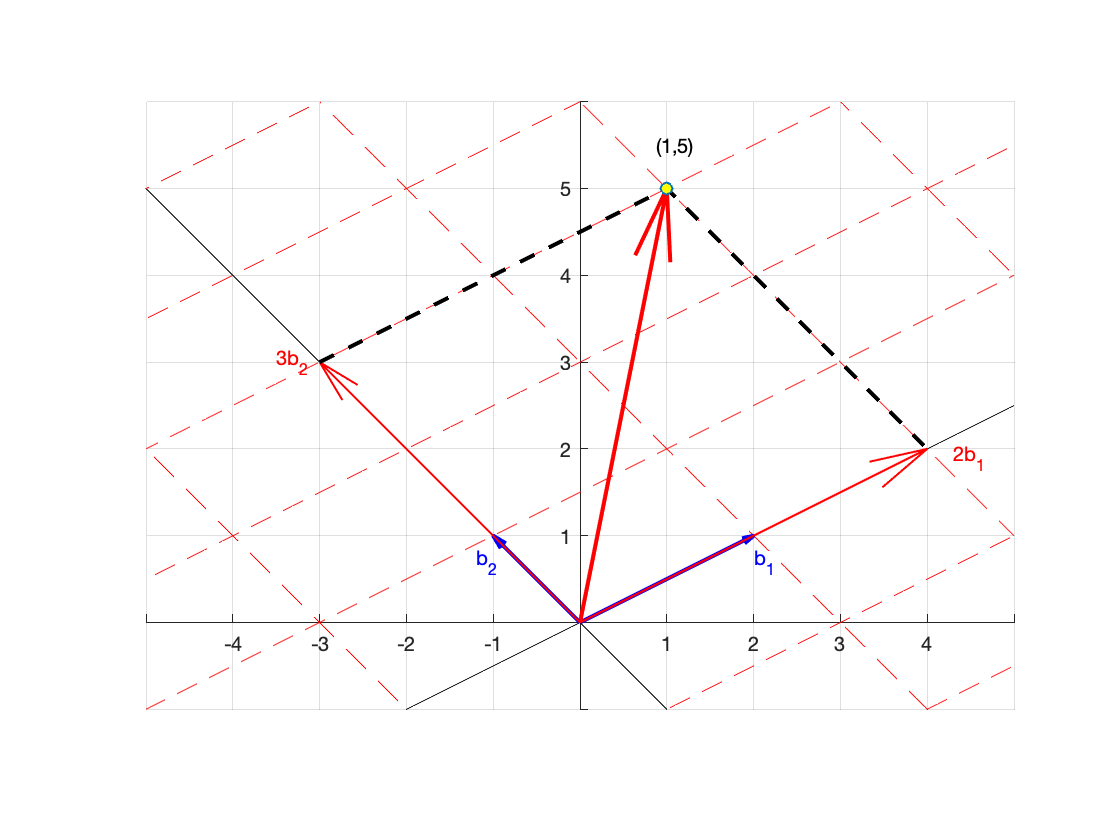

figure, hold on
t=linspace(-5,5);
for k=-5:5
    plot(2*k-t,k+t,'r--')
    plot(-k+2*t,k+t,'r--')
end
plot(2*t,t,'k')
plot(-t,t,'k')
quiver(0,0,2,1,0,'LineWidth',2,'Color','b')
quiver(0,0,-1,1,0,'LineWidth',2,'Color','b','MaxHeadSize',0.5)
quiver(0,0,4,2,0,'LineWidth',1,'Color','r','MaxHeadSize',0.5)
quiver(0,0,-3,3,0,'LineWidth',1,'Color','r','MaxHeadSize',0.5)
quiver(0,0,1,5,0,'LineWidth',2,'Color','r','MaxHeadSize',0.5)
line([-3,1,4],[3 5 2],'LineStyle','--','LineWidth',2,'Color','k')
plot(1,5,'o','MarkerFaceColor','y')
axis equal
axis([-5,5,-1,6])
grid on
xticks(-5:5)
yticks(-1:6)
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
text(2,0.7,'b_1','Color','b')
text(-1.2,0.7,'b_2','Color','b')
text(4.3,1.9,'2b_1','Color','r')
text(-3.5,3,'3b_2','Color','r')
text(1.1,5.5,'(1,5)','HorizontalAlignment','center')
hold off

We were given the vector $\vec v=\pmatrix{1\cr 5}$. Note that the tip of the large red arrow is at the point $(1,5)$ in the standard coordinate system for $R^2$.  Now, our answer was $\left[\vec v\right]_B=\pmatrix{2\cr 3}$. Note that $2\vec b_1+3\vec b_2$ in our image gives us $\pmatrix{1\cr 5}$ using the parallelogram method for adding vectors, so we are correct thus far. 

Our second task was to transform $\left[\vec v\right]_B=\pmatrix{2\cr 3}$ into $C$-coordinates using the transition matrix found in Example #3, which was:


$$P_{C\leftarrow B}=\pmatrix{5/4 & 1/2\cr -1/4 & 1/2}$$


We can recalculate $P_{C\leftarrow B}$ again to get some more practice with our technique.

B=[2 -1;1 1];
C=[1 -3;1 1];
N=[C,B]

N =      1    -3     2    -1
     1     1     1     1


N=rref(sym(N))

$$N = \left(\begin{array}{cccc} 1 & 0 & \frac{5}{4} & \frac{1}{2}\\ 0 & 1 & -\frac{1}{4} & \frac{1}{2} \end{array}\right)$$

PCB=N(:,[3,4])

$$PCB = \left(\begin{array}{cc} \frac{5}{4} & \frac{1}{2}\\ -\frac{1}{4} & \frac{1}{2} \end{array}\right)$$

Same answer. To find the $C$-coordinates of our vector, we need to perform the following operation.


$$\left[\vec v\right]_C=P_{C\leftarrow B}\left[\vec v\right]_B$$


We stored $\left[\vec v\right]_B=\pmatrix{2\cr 3}$ above in vB, so:

vC=PCB*vB

$$vC = \left(\begin{array}{c} 4\\ 1 \end{array}\right)$$

Now, does $\left[\vec v\right]_C=\pmatrix{4\cr 1}$  make sense? Let's visualize this answer. 

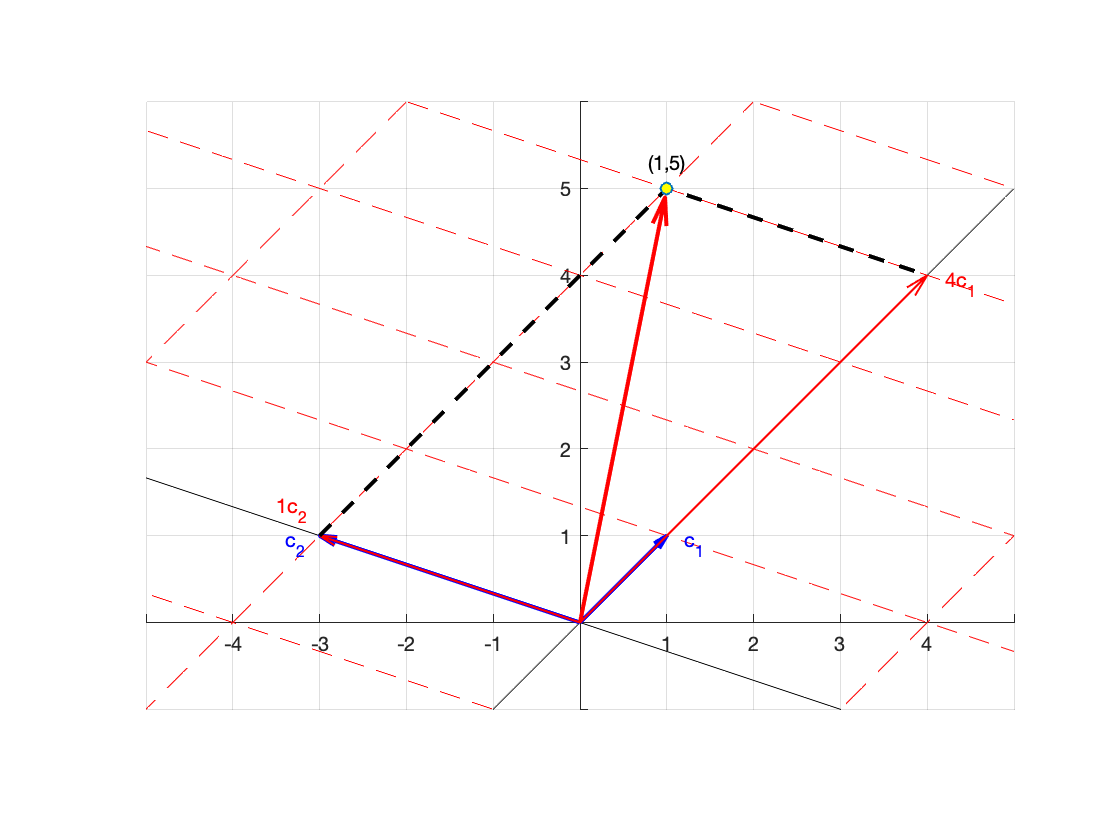

figure, hold on
t=linspace(-5,5);
for k=-5:5
    plot(k-3*t,k+t,'r--')
    plot(-3*k+t,k+t,'r--')
end
plot(-3*t,t,'k')
plot(t,t,'k')
quiver(0,0,-3,1,0,'LineWidth',2,'Color','b')
quiver(0,0,1,1,0,'LineWidth',2,'Color','b','MaxHeadSize',0.5)
quiver(0,0,1,5,0.98,'LineWidth',2,'Color','r','MaxHeadSize',0.2)
quiver(0,0,4,4,0,'LineWidth',1,'Color','r','MaxHeadSize',0.2)
quiver(0,0,-3,1,0,'LineWidth',1,'Color','r','MaxHeadSize',0.2)
line([-3,1,4],[1,5,4],'LineStyle','--','LineWidth',2,'Color','k')
plot(1,5,'o','MarkerFaceColor','y')
axis equal
axis([-5,5,-1,6])
grid on
xticks(-5:5)
yticks(-1:6)
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
text(1.2,0.9,'c_1','Color','b')
text(-3.4,0.9,'c_2','Color','b')
text(4.2,3.9,'4c_1','Color','r')
text(-3.5,1.3,'1c_2','Color','r')
text(1,5.3,'(1,5)','Color','k','HorizontalAlignment','center')
hold off

We were given the vector $\vec v=\pmatrix{1\cr 5}$. Note that the tip of the large red arrow is at the point $(1,5)$ in the standard coordinate system for $R^2$.  Now, our answer was $\left[\vec v\right]_C=\pmatrix{4\cr 1}$. Note that $4\vec c_1+1\vec c_2$ in our image gives us $\pmatrix{1\cr 5}$ using the parallelogram method for adding vectors, so we've done this correctly.